# HomeWork n.1 2021/22

### *Pezzolla Luca 0124002411*

***PUNTO 1:***

*Definite la function Matlab che implementa la vostra funzione di riferimento e che chiamerete *`funrif;`


$$e^{-x} \cdot (cos(\frac {p \cdot x}{2}-\pi/2))^2 +  \frac {q}{1+2x^2}cos(2x)-3$$


In questo specifico caso il valore associato a p è 4, mentre il valore associato a q è 8. Tali valori rappresentano rispettivamente il numero di caratteri del mio nome e cognome.

funrif = @(x) exp(-x).*(cos(4*x/2-pi/2)).^2 + 8./(1+2*x.^2).*cos(2*x)-3;

Visualizzazione della funzione nell'intervallo [-4, 1] :

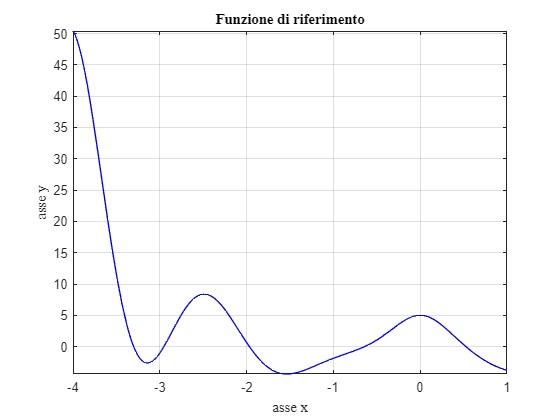

format long
figure(1)
fplot(funrif,[-4,1],'color','b')

hold on
grid on

xlabel("asse x",'FontName','Times New Roman')
ylabel("asse y",'FontName','Times New Roman')
title("Funzione di riferimento",'FontName','Times New Roman')

***PUNTO 2:***

*Visualizzate il grafico della funzione di riferimento in *$[a,b]$*, specificando espicitamente quale intervallo avete scelto e indicando sul grafico (comando text) gli estremi dell'intervallo scelto, i 5 zeri, il primo valore minimo e l'ascissa del primo minimo (detta punto di minimo 1), il secondo valore minimo e l'ascissa del secondo minimo (detta punto di minimo 2), il primo valore massimo e l'ascissa del primo massimo (detta punto di massimo 1), il secondo valore massimo e l'ascissa del secondo massimo (detta punto di massimo 2);*

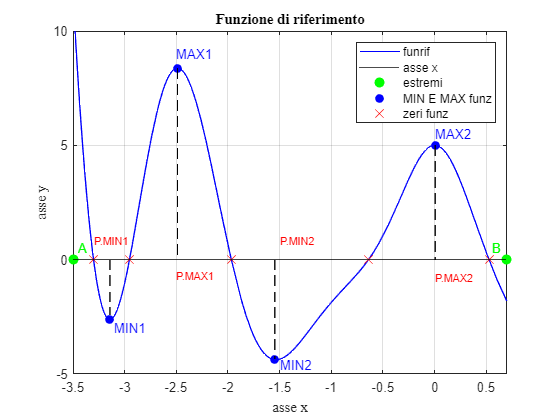

figure(2)
fplot(funrif,[-4,1],'color','b')
%Comando per specificare i limiti dell'intervallo in cui visualizzare la
%funzione di riferimento
axis([-3.5,0.7,-5,10])

hold on 
grid on 

xlabel("asse x",'FontName','Times New Roman')
ylabel("asse y",'FontName','Times New Roman')
title("Funzione di riferimento",'FontName','Times New Roman')

%Comando per visualizzare l'asse delle ascisse
yline(0,'-','color','k')

%Comando per visualizzare gli estremi dell'intervallo, A = -3.5, B = 0.7
text(-3.45,0.5,'A', "Color", 'g')
text(0.55,0.5,'B', 'color','g')

plot([-3.5,0.7],[0,0],'o','markersize',7,'color','g','MarkerFaceColor','g')

%Comando per evidenziare i minimi e i massimi della funzione di riferimento
text(-3.1,-3, "MIN1","Color",'b')
text(-1.5,-4.6, "MIN2","Color",'b')
text(-2.5,9,"MAX1","Color",'b')
text(0,5.5,"MAX2","Color",'b')
plot([-3.146 -2.487 -1.546 0.0045], [-2.61 8.37 -4.37 5], 'o','color','b','MarkerFaceColor','b')

%I punti di zero sono stati segnati con una 'x' e sono stati trovati
%mediante funzione fzero
plot([-3.301010073372643  -2.953119453970817 -1.967913905994130 -0.640222827703433  0.525940931810359],[0 0 0 0 0],'x','markersize',9,'color','r')

%Proiezione punti di min e max
plot([-3.14267,-3.14267], [0,-2.406], '--','color','k')
plot([-2.48731,-2.48731], [8.37,0], '--','color','k')
plot([-1.54677,-1.54677], [0,-4.37], '--','color','k')
plot([0.0045,0.0045], [5,0], '--','color','k')

text(-3.3,0.8,'P.MIN1', "Color", 'r',"FontSize",8)
text(-2.5,-0.7,'P.MAX1', "Color", 'r',"FontSize",8)
text(-1.5,0.8,'P.MIN2', "Color", 'r',"FontSize",8) 
text(0,-0.8,'P.MAX2', "Color", 'r',"FontSize",8) 
legend('funrif','asse x','estremi','MIN E MAX funz','zeri funz')

**PUNTO 3:**

*Usate la function Matlab *`fzero`* per determinare i 5 zeri della vostra funzione di riferimento in *$[a,b]$*, e considerate i valori calcolati da *`fzero`* come le soluzioni esatte; *

Per calcolare i 5 zeri della funzione utilizziamo la function Matlab fzero, la quale ha il vantaggio di convergere sempre. 

La funzione prende in input la funzione di riferimento e l'approssimazone iniziale della soluzione, oppure un intervallo contentente la soluzione.

z1 = fzero(funrif,[-3.5, -3.3])

z1 =   -3.301010073372643


z2 = fzero(funrif,[-3, -2.5])

z2 =   -2.953119453970817


z3 = fzero(funrif,[-2,-1.5])

z3 =   -1.967913905994130


z4 = fzero(funrif,[-1 0])

z4 =   -0.640222827703433


z5 = fzero(funrif,[0 0.7])

z5 =    0.525940931810359


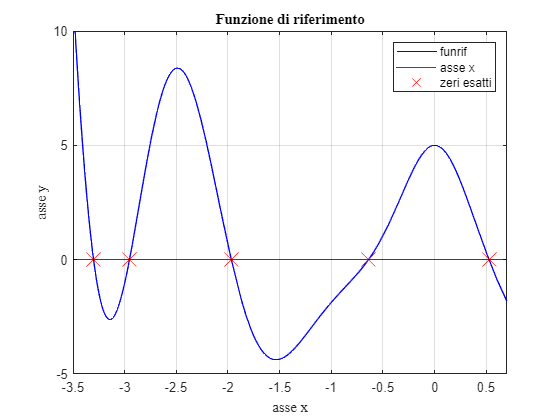

figure(3)
fplot(funrif,[-4,1],'color','b')
axis([-3.5,0.7,-5,10])

hold on 
grid on 

xlabel("asse x",'FontName','Times New Roman')
ylabel("asse y",'FontName','Times New Roman')
title("Funzione di riferimento",'FontName','Times New Roman')

yline(0,'-','color','k') 

%Visualizzo i 5 zeri della mia funzione di riferimento
plot([-3.301010073372643  -2.953119453970817 -1.967913905994130 -0.640222827703433  0.525940931810359],[0 0 0 0 0],'x','markersize',15,'color','r') 
legend('funrif','asse x','zeri esatti')

I 5 zeri calcolati con la funzione fzero sono stati opportunamente rappresentati all'interno del grafico,

**PUNTO 4:**

*Determinate un'approssimazione dei 5 zeri, usando il metodo di bisezione (nostra function *`bisezione`*) per lo zero più piccolo, il metodo delle Secanti (nostra function *`Secanti`*) per il secondo e terzo zero e il metodo di Newton (nostra function *`Newton`*) per il quarto e il quinto zero (consiglio: usare *`funtool`* per determinare l'espressione della derivata della funzione di riferimento), con un valore di *`delta_ass`* che garantisca, in tutti e 5 i casi, che la parte intera e le prime 6 cifre frazionarie siano corrette;*

**Metodo di Bisezione:**

Il metodo di bisezione è un algoritmo iterativo globale e a velocità di convergenza lineare che risolve il problema *f(x) = 0*; è utilizzabile se f è una funzione continua e se si conosce un intervallo che contiene la soluzione e ai cui estremi la f assume valori di segno opposto. Con globale si intende che l’algoritmo è sempre convergente (quando è applicabile!). Con velocità di convergenza lineare si intende che l’errore si riduce di un fattore costante a ogni passo di iterazione.

L’algoritmo è basato sull’approccio detto divide et impera, che riduce progressivamente (dimezzandolo a ogni passo) l’intervallo che contiene la soluzione.

%Scelgo il delta_ass uguale a 1e-6 in modo tale che nei cinque casi la
%parte intera e le prime 6 cifre frazionarie siano corrette
delta_ass = 1e-6;

%Il primo argomento di input del metodo di bisezione è l'handle alla function che implementa la funzione funrif,
%il secondo e il terzo sono gli estremi dell'intervallo, l'ultimo argomento è l'accuratezza che si vuole sul risultato 
%(il delta_ass che abbiamo fissato in precedenza)
zero_bis = bisezione(funrif,-3.5,-3.3,delta_ass)

zero_bis =   -3.301009750366211


**Metodo delle Secanti:**

Il metodo delle secanti è un algoritmo iterativo locale e a velocità di convergenza superlineare che risolve il problema *f(x) = 0;* è utilizzabile se f è una funzione continua e se si conosce una buona approssimazione iniziale della soluzione.

Con locale si intende che l’algoritmo non è sempre convergente e che la convergenza dipende da come si sceglie la condizione iniziale. Con velocità di convergenza superlineare si intende che, a ogni passo di iterazione, l’errore relativo si riduce diventando una potenza dell’errore precedente L’algoritmo è basato sull’idea di approssimare linearmente la f, a ogni passo p di iterazione, con la retta che passa per i due punti *(xp, f(xp)) e (xp-1, f(xp-1))*, il cui coefficiente angolare è *(f(xp) - f(xp-1)) /(xp - xp-1)*, e di considerare lo zero di tale retta come approssimazione dello zero di f.

kmax = 10; %numero massimo di iterazioni consentite
% Il primo parametro di input del metodo Secanti è l'handle alla function
% funrif, il secondo e il terzo argomento sono le prime due approssimazioni
% iniziali, il quarto argomento (delta_ass) è l'accuratezza richiesta,
% mentre il quinto argomento (kmax) è il numero massimo di iterazioni consentite
zero_sec1 = Secanti(funrif,-3,-2.5,delta_ass,kmax)

zero_sec1 =   -2.953119450016811


zero_sec2 = Secanti(funrif,-2,-1.5,delta_ass,kmax)

zero_sec2 =   -1.967913891290388


**Metodo di Newton:**

Il metodo di Newton è un algoritmo iterativo locale e a velocità di convergenza quadratica che risolve il problema *f(x) = 0*; è utilizzabile se f è una funzione continua e derivabile (con derivata nota) e se si conosce una buona approssimazione iniziale della soluzione. Con locale si intende che l’algoritmo non è sempre convergente e che la convergenza dipende da come si sceglie la condizione iniziale. Con velocità di convergenza quadratica si intende che, a ogni passo di iterazione, l’errore relativo si riduce diventando il quadrato dell’errore precedente.

L’algoritmo è basato sull’idea di approssimare linearmente la f, a ogni passo p di iterazione, con la retta tangente alla f nel punto *(xp, f(xp))*, il cui coefficiente angolare1 è *f’(xp)*, e di considerare lo zero di tale retta come approssimazione dello zero di f.

La derivata prima di funrif è stata calcolata con funtool: 

derivata_prima = @(x) -cos(2*x - pi/2).^2.*exp(-x) - (16*sin(2*x))./(2*x.^2 + 1) - (32*x.*cos(2*x))./(2*x.^2 + 1).^2 - 4*cos(2*x - pi/2).*sin(2*x - pi/2).*exp(-x)

derivata_prima = function_handle with value:
    @(x)-cos(2*x-pi/2).^2.*exp(-x)-(16*sin(2*x))./(2*x.^2+1)-(32*x.*cos(2*x))./(2*x.^2+1).^2-4*cos(2*x-pi/2).*sin(2*x-pi/2).*exp(-x)


%Il primo parametro del metodo di Newton è l'handle alla function fanrif,
%il secondo parametro è l'handle alla function derivataprima, il terzo
%argomento è l'approssimazione iniziale, il quarto argomento è
%l'accuratezza richiesta mentre l'ultimo argomento è il numero massimo di
%iterazioni consentite
zero_new1 = Newton(funrif,derivata_prima,-0.64,delta_ass,kmax)

zero_new1 =   -0.640222772729113


zero_new2= Newton(funrif,derivata_prima,0.52,delta_ass,kmax)

zero_new2 =    0.525940931621976


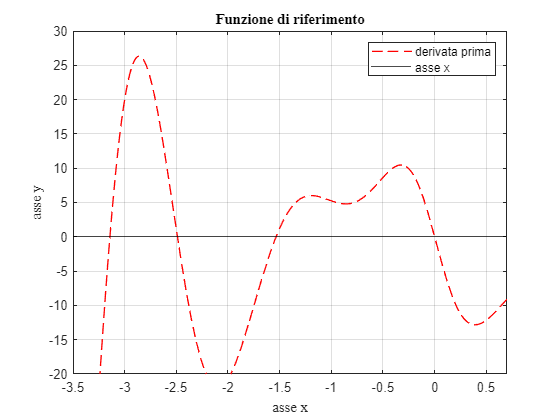

figure(4)
hold off
%Visualizzo graficamente la derivata prima nell'intervallo [a,b]
fplot(derivata_prima,[-4,1],"--","LineWidth",1,'color','r') 
axis([-3.5,0.7,-20,30])

hold on
grid on

xlabel("asse x",'FontName','Times New Roman')
ylabel("asse y",'FontName','Times New Roman')
title("Funzione di riferimento",'FontName','Times New Roman')

yline(0,'-','color','k')

legend('derivata prima', 'asse x')

**PUNTO 5:**

*Considerate sia l'errore assoluto tra l'approssimazione della bisezione e la corrispondente soluzione esatta, sia l'errore assoluto tra l'approssimazione delle Secanti e la corrispondente soluzione esatta (per entrambi gli zeri calcolati con le Secanti), sia l'errore assoluto tra l'approssimazione di Newton e la corrispondente soluzione esatta (per entrambi gli zeri calcolati con Newton) e verificate che siano minori dell'accuratezza richiesta (*`delta_ass`*), commentando il loro valore; calcolate anche il residuo per ognuna delle cinque approssimazioni e commentate i valori del residuo confrontandoli con quelli del corrispondente errore assoluto  e con l'accuratezza richiesta; guardando il grafico della funzione di riferimento dire se, per ognuno dei cinque zeri, il problema appare bene o mal condizionato e poi calcolare l'indice di condizionamento per ognuno dei cinque zeri;*

Errore assoluto per il metodo della Bisezione:

%Calcolo errore assoluto tra l'approssimazione della bisezione e la corrispondente soluzione esatta
err_bis = abs(zero_bis - z1)

err_bis =      3.230064322679027e-07


%Controllo logico
if(err_bis <= delta_ass)
    fprintf('Approssimazione del metodo di Bisezione minore della accuratezza richiesta')
else 
    fprintf('Approssimazione del metodo di Bisezione maggiore della accuratezza richiesta')
end

Approssimazione del metodo di Bisezione minore della accuratezza richiesta

Errore assoluto per il metodo delle Secanti:

%Calcolo errore assoluto tra l'approssimazione delle Secanti e la corrispondente soluzione esatta
err_sec1 = abs(zero_sec1 - z2)

err_sec1 =      3.954005567408103e-09


%Controllo logico
if(err_sec1 <= delta_ass)
    fprintf('Approssimazione del metodo delle Secanti minore della accuratezza richiesta')
else 
    fprintf('Approssimazione del metodo delle Secanti maggiore della accuratezza richiesta')
end

Approssimazione del metodo delle Secanti minore della accuratezza richiesta

err_sec2 = abs(zero_sec2 - z3)

err_sec2 =      1.470374222378723e-08


%Controllo logico
if(err_sec2 <= delta_ass)
    fprintf('Approssimazione del metodo delle Secanti minore della accuratezza richiesta')
else 
    fprintf('Approssimazione del metodo delle Secanti maggiore della accuratezza richiesta')
end

Approssimazione del metodo delle Secanti minore della accuratezza richiesta

Errore assoluto per il metodo di Newton:

%Calcolo errore assoluto tra l'approssimazione di Newton e la corrispondente soluzione esatta
err_new1 = abs(zero_new1 - z4)

err_new1 =      5.497432054024642e-08


%Controllo logico
if(err_new1 <= delta_ass)
    fprintf('Approssimazione del metodo di Newton minore della accuratezza richiesta')
else 
    fprintf('Approssimazione del metodo di Newton maggiore della accuratezza richiesta')
end

Approssimazione del metodo di Newton minore della accuratezza richiesta

err_new2 = abs(zero_new2 - z5)

err_new2 =      1.883833089522113e-10


%Controllo logico
if(err_new2 <= delta_ass)
    fprintf('Approssimazione del metodo di Newton minore della accuratezza richiesta')
else 
    fprintf('Approssimazione del metodo di Newton maggiore della accuratezza richiesta')
end

Approssimazione del metodo di Newton minore della accuratezza richiesta

Calcolo dei residui: 

Il residuo è la misura di quanto una soluzione approssimata soddisfa il problema. Si calcola attraverso il valore assoluto della funzione funrif calcolata prima nello zero di bisezione, poi negli zeri del metodo delle Secanti e poi negli zeri calcolati con il metodo di Newton.

%Residuo metodo di Bisezione:
residuo_zero_bis = abs(funrif(zero_bis))

residuo_zero_bis =      1.116563141057014e-05


L'ordine di grandezza del residuo dell'approssimazione del metodo di bisezione è di poco minore all'accuratezza richiesta 10^-6 , ma il problema è comunque ben condizionato.

%Residuo metodo delle Secanti:
residuo_zero_sec1 = abs(funrif(zero_sec1))

residuo_zero_sec1 =      9.323317007314813e-08


residuo_zero_sec2 = abs(funrif(zero_sec2))

residuo_zero_sec2 =      2.916110881656664e-07


L'ordine di grandezza del residuo dell'approssimazione del metodo delle Secanti è in entrambi i casi minore all'accuratezza richiesta 10^-6 , quindi il problema è ben condizionato.

%Residuo metodo di Newton
residuo_zero_new1 = abs(funrif(zero_new1))

residuo_zero_new1 =      3.503338952270951e-07


residuo_zero_new2 = abs(funrif(zero_new2))

residuo_zero_new2 =      2.229025852784616e-09


L'ordine di grandezza del residuo dell'approssimazione del metodo di Newton è in entrambi i casi minore all'accuratezza richiesta 10^-6 , quindi il problema è ben condizionato.

Calcolo degli indici di condizionamento: 

Il condizionamento riguarda il rapporto tra errore commesso sul risultato di un calcolo e incertezza sui dati in ingresso.Un problema è ben condizionato quando la soluzione del problema con delle piccole variazioni, non differisce molto dalla soluzione del problema originale; al contrario, un problema mal condizionato è un problema dove le soluzioni sono molto sensibili a piccole perturbazioni dei dati iniziali.

%Indice di condizionamento per il primo zero della funzione
k1 = 1/abs(derivata_prima(z1))

k1 =    0.028928598557141


%Indice di condizionamento per il secondo zero della funzione
k2 = 1/abs(derivata_prima(z2))

k2 =    0.042409860179331


%Indice di condizionamento per il terzo zero della funzione
k3 = 1/abs(derivata_prima(z3))

k3 =    0.050422437956460


%Indice di condizionamento per il quarto zero della funzione
k4 = 1/abs(derivata_prima(z4))

k4 =    0.156919797530794


%Indice di condizionamento per il quinto zero della funzione
k5 = 1/abs(derivata_prima(z5))

k5 =    0.084513752639410


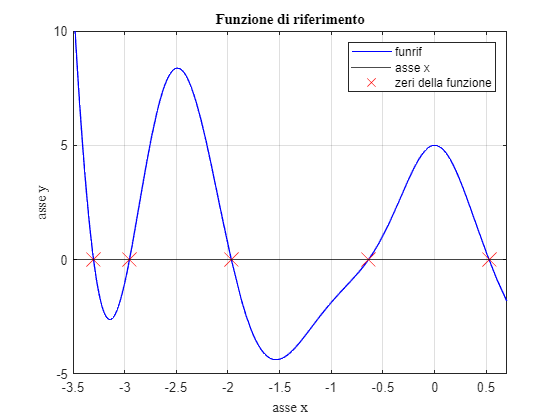

figure(5)
fplot(funrif,[-4,1],'color','b')
axis([-3.5,0.7,-5,10])

hold on 
grid on 

xlabel("asse x",'FontName','Times New Roman')
ylabel("asse y",'FontName','Times New Roman')
title("Funzione di riferimento",'FontName','Times New Roman')

yline(0,'-','color','k')

plot([z1 z2 z3 z4 z5],[0 0 0 0 0],'x','markersize',15,'color','r')
legend('funrif', 'asse x', 'zeri della funzione')

Il problema della ricerca degli zeri della nostra funzione di riferimento è ben condizionato. Due conferme ci arrivano sia dal fatto che gli indici di condizionamento calcolati nei cinque punti siano molto piccoli, sia dal fatto che la funzione non è schiacciata quando interseca l'asse delle ascisse.

**PUNTO 6:**

*Osservando il grafico della vostra funzione di riferimento nell'intervallo *$[a,b]$*e della bisettrice, stabilite se ci sono punti fissi e determinate il loro numero; poi, senza usare la function *`PFisso (suggerimento: `*usate opportunamente*` fzero)`*, calcolate una approssimazione del punto fisso più vicino all'estremo sinistro dell'intervallo, cioè più vicino ad *$a$*, e determinate il residuo; dite se il metodo del punto fisso convergerebbe a tale punto fisso.*

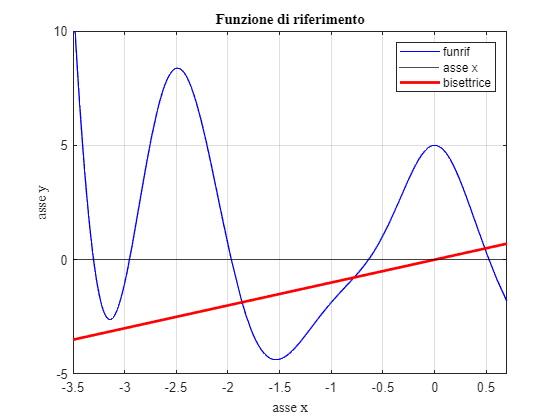

figure(6)
fplot(funrif,[-4,1],'color','b')
axis([-3.5,0.7,-5,10])

hold on 
grid on 

xlabel("asse x",'FontName','Times New Roman')
ylabel("asse y",'FontName','Times New Roman')
title("Funzione di riferimento",'FontName','Times New Roman')

yline(0,'-','color','k')

%Visualizzo la bisettrice del primo e terzo quadrante (y = x)
xx = linspace(-3.5,0.7,10);
plot(xx,xx,'r','linewidth',2) 
legend('funrif','asse x','bisettrice')

Da come è possibile osservare dal grafico, la bisettrice interseca la nostra funzione di riferimento (nell'intervallo [-3.5,0.5]) in tre punti. 

Per calcolare il punto fisso senza usare l'apposita funzione PFisso è necessario procedere nella seguente maniera: dal momento in cui il problema del punto fisso consiste nel risolvere l'equazione "*f(x) = x*", possiamo portare la nostra x a sinistra e ricondurci al problema *"f(x) - x = 0"*. In questo modo sarà possibile utilizzare la funzione fzero messa a disposizione da Matlab e trovare così il punto fisso più vicino all'estremo sinistro **a** (nel nostro caso uguale a -3.5).

pf1 = fzero(@(x)funrif(x)-x,-3.5) 

pf1 =   -1.863959048941634


Calcolo del residuo: 

abs(funrif(pf1) - pf1)

ans =      1.110223024625157e-15


Per sapere se il metodo del punto fisso convergerebbe o meno al punto fisso calcolato, basta valutare la derivata in pf1 e vedere se essa è minore o maggiore di 1. Se essa è minore allora possiamo dire che il metodo convergerebbe, in caso contrario divergerebbe.

abs(derivata_prima(pf1))

ans =   15.764067806032610


Il metodo del punto fisso non convergerebbe in quanto la derivata in pf1 è maggiore di 1.

**PUNTO 7:**

*Usate la function Matlab *`fminbnd`* per determinare i due punti di minimo e i due punti di massimo della vostra funzione di riferimento in *$[a,b]$*, con quattro chiamate del tipo: *`fminbnd(fun,sinistro,destro,optimset('TolX',1e-10))`*, e considerate i valori calcolati da *`fminbnd`* come le soluzioni esatte (cioè come valori esatti dei due punti di minimo e dei due punti di massimo);*

%La function fminbnd calcola il punto di minimo di una funzione.
%La function fminbnd ha tre parametri di input: il primo è l'handle alla function Matlab che
%implementa la funzione f; il secondo e il terzo argomento sono, rispettivamente, l'estremo sinistro e
%l'estremo destro di un intervallo che contiene la soluzione.

MIN1 = fminbnd(funrif,-3.2,-3,optimset('TolX',1e-10')) 

MIN1 =   -3.142861915568317


%Per il calcolo del punto di massimo con la fminbnd è necessario passare
%come primo argomento l'handle alla funzione opposta a funrif
MAX1 = fminbnd(@(x)-funrif(x),-2.5,-2.4,optimset('TolX',1e-10'))

MAX1 =   -2.489480876964806


MIN2 = fminbnd(funrif,-2,-1,optimset('TolX',1e-10'))

MIN2 =   -1.534994604703379


MAX2 = fminbnd(@(x)-funrif(x),0,0.3,optimset('TolX',1e-10'))

MAX2 =      2.180413988247903e-09


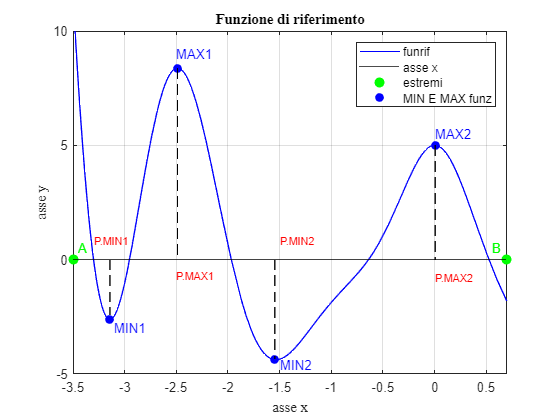

figure(7)
fplot(funrif,[-4,1],'color','b')
axis([-3.5,0.7,-5,10])

hold on 
grid on 

xlabel("asse x",'FontName','Times New Roman')
ylabel("asse y",'FontName','Times New Roman')
title("Funzione di riferimento",'FontName','Times New Roman')

yline(0,'-','color','k')

text(-3.45,0.5,'A', "Color", 'g')
text(0.55,0.5,'B', 'color','g')

plot([-3.5,0.7],[0,0],'o','markersize',7,'color','g','MarkerFaceColor','g')

text(-3.1,-3, "MIN1","Color",'b')
text(-1.5,-4.6, "MIN2","Color",'b')
text(-2.5,9,"MAX1","Color",'b')
text(0,5.5,"MAX2","Color",'b')
plot([-3.146 -2.487 -1.546 0.0045], [-2.61 8.37 -4.37 5], 'o','color','b','MarkerFaceColor','b')

plot([-3.14267,-3.14267], [0,-2.406], '--','color','k')
plot([-2.48731,-2.48731], [8.37,0], '--','color','k')
plot([-1.54677,-1.54677], [0,-4.37], '--','color','k')
plot([0.0045,0.0045], [5,0], '--','color','k')

text(-3.3,0.8,'P.MIN1', "Color", 'r',"FontSize",8)
text(-2.5,-0.7,'P.MAX1', "Color", 'r',"FontSize",8)
text(-1.5,0.8,'P.MIN2', "Color", 'r',"FontSize",8) 
text(0,-0.8,'P.MAX2', "Color", 'r',"FontSize",8) 
legend('funrif','asse x','estremi','MIN E MAX funz')

**PUNTO 8:**

*Verificate che i due punti di minimo e i due punti di massimo sono zeri della derivata della vostra funzione di riferimento (consiglio: usare *`funtool`* per determinare l'espressione della derivata della funzione di riferimento), visualizzando nella stessa figura sia il grafico della funzione sia il grafico della sua derivata (può essere utile usare anche la scalatura della finestra grafica data dal comando *`axis([xmin xmax ymin ymax])`* ), e usando la *`fzero`* per calcolare tutti gli zeri della derivata; commentate i risultati ottenuti;*

Per dimostrare che i due punti di minimo e di massimo sono zeri della derivata della nostra funzione basta utilizzare la function fzero sulla derivata prima. Se essi coincidono con i massimi e minimi trovati nel punto 7, allora i punti sono gli zeri della derivata. Difatti, l'annullamento della derivata in un determinato punto indica che quel punto è un massimo o un minimo.

zd1 = fzero(derivata_prima,-3.14)

zd1 =   -3.142861928034298


zd2 = fzero(derivata_prima,-2.48)

zd2 =   -2.489480873471378


zd3 = fzero(derivata_prima,-1.53)

zd3 =   -1.534994597578430


zd4 = fzero(derivata_prima,0.1)

zd4 =      9.169562329568760e-18


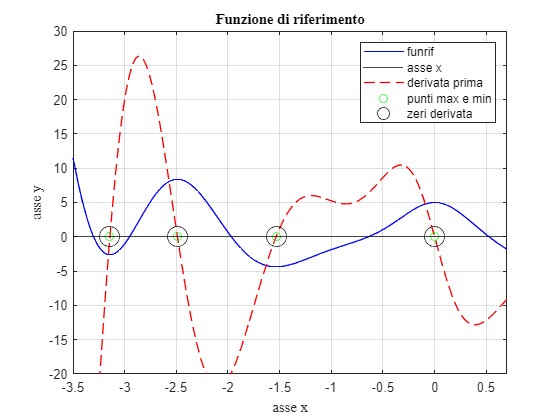

figure(8)
fplot(funrif,[-4,1],'color','b')
axis([-3.5,0.7,-20,30])

hold on 
grid on 

xlabel("asse x",'FontName','Times New Roman')
ylabel("asse y",'FontName','Times New Roman')
title("Funzione di riferimento",'FontName','Times New Roman') 

yline(0,'-','color','k')

fplot(derivata_prima,[-4,1],"--","LineWidth",1,'color','r')  

plot([MIN1 MAX1 MIN2 MAX2],[0 0 0 0],'o','markersize',6,'color','g') 

plot([zd1 zd2 zd3 zd4],[0 0 0 0],'o','markersize',15,'color','k')

legend('funrif','asse x','derivata prima','punti max e min','zeri derivata')

Da come è possibile vedere dal grafico, i punti di minimo e massimo e gli zeri della derivata coincidono, esattamente come ci si aspettava.

**PUNTO 9:**

*Determinate un'approssimazione dei due punti di minimo e dei due punti di massimo, usando, rispettivamente, due volte il metodo di Fibonacci search (nostra function *`fminfibo`*) per i due minimi, e il metodo di Golden search (nostra function *`fmingolden`*) per i due massimi, con un valore di *`delta_ass`* che garantisca che la parte intera e le prime 3 cifre frazionarie siano corrette;*

Per usare il metodo di Fibonacci search e il Golden search devo scegliere degli intervalli tali che la funzione risulti unimodale: Una funzione f è unimodale in [a,b] se esiste un unico numero r in [a,b] tale che f è decrescente in [a,r] ed è crescente in [r,b].

L'algoritmo di ricerca di Fibonacci (Fibonacci Search) comincia scegliendo un intero N e calcolando i numeri di Fibonacci da 1 ad N. I parametri di input sono: l'handle alla funzione di riferimento,"a" estremo sinistro dell'intervallo che contiene la soluzione, "b" estremo destro dello stesso intervallo e l'accuratezza richiesta sulla soluzione. Nel nostro caso delta_ass deve essere uguale a 1e-3.

%Primo punto di minimo di Fibonacci search
minf1 = fminfibo(funrif,-3.18,-3,1e-3)

minf1 =   -3.142363636363636


%Secondo punto di minimo di Fibonacci search
minf2 = fminfibo(funrif,-2,-1,1e-3)

minf2 =   -1.534482758620690


Il metodo della ricerca aurea o Golden Search può essere considerato come una variante del metodo di Fibonacci. Esso si basa su risultati noti sulla successione dei numeri di Fibonacci. Come è noto la sezione aurea, per definizione, è il limite per n->inf di F(N)/F(N-1). Quindi il rapporto tra due numeri di Fibonacci consecutivi tende al valore della sezione aurea (circa 1.6180).  

In input abbiamo: l'handle alla funzione di riferimento, gli estremi sinistro e destro dell'intervallo che racchiudono la soluzione, e l'accuratezza richiesta (1e-3).

%Primo punto di massimo di golden search
maxg1 = fmingolden(funrif,-2.49,-2.489,1e-3)

maxg1 =   -2.489500000000000


%Secondo punto di massimo di golden search
maxg2 = fmingolden(funrif,-0.001,0,1e-3)

maxg2 =     -5.000000000000000e-04


**PUNTO 10:**

*Considerate l'errore assoluto tra le due approssimazioni ottenute dalle due chiamate alla Golden search e le due corrispondenti soluzioni esatte e poi l'errore assoluto tra le due approssimazioni ottenute dalle due chiamate alla Fibonacci search e le due corrispondenti soluzioni esatte, e verificate che siano in tutti e quattro i casi minori dell'accuratezza richiesta (*`delta_ass`*), commentando i risultati;*

%Calcolo errore assoluto metodo Golden Search per il primo massimo
err_ass_g1 = abs(maxg1-MAX1)

err_ass_g1 =      1.912303519446823e-05


err_ass_g1 < 1e-3

ans = logical
   1


L'errore assoluto è minore dell'accuratezza per il primo massimo.

%Calcolo errore assoluto metodo Golden Search per il secondo massimo
err_ass_g2 = abs(maxg2-MAX2)

err_ass_g2 =      5.000021804139883e-04


err_ass_g2 < 1e-3

ans = logical
   1


L'errore assoluto è minore dell'accuratezza per il secondo massimo.

%Calcolo errore assoluto metodo di Fibonacci per il primo minimo 
err_ass_f1=abs(minf1-MIN1)

err_ass_f1 =      4.982792046801521e-04


err_ass_f1 < 1e-3

ans = logical
   1


L'errore assoluto è minore dell'accuratezza per il primo minimo.

%Calcolo errore assoluto metodo di Fibonacci per il secondo minimo 
err_ass_f2=abs(minf2-MIN2)

err_ass_f2 =      5.118460826893934e-04


err_ass_f2 < 1e-3

ans = logical
   1


L'errore assoluto è minore dell'accuratezza per il secondo minimo.